# **天线阵的方向图演示（天线工具箱仿真计算）**

**        Antenna Toobox 还支持天线阵的建模和分析。MATLAB提供各种天线供用户选择。可以从目录中选择天线或确定自定义单元设计线形、矩形、圆形和共形等各种类型的天线阵列。下面这个例子将给出如何通过Antenna Toolbox 创建和可视化一个天线阵。**

- **创建天线阵**

**      使用阵列库中的 rectangularArray 创建一个矩形天线阵 ra，一般默认天线单元为偶极子天线。**

ra=rectangularArray

ra =   rectangularArray - 属性:

           Element: [1×1 dipole]
              Size: [2 2]
        RowSpacing: 2
     ColumnSpacing: 2
           Lattice: 'Rectangular'
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


- **天线阵平面结构的可视化**

**        使用 layout 函数在 xoy 平面绘制天线阵中每个单元天线的位置，一般默认矩形阵列是由 4 个偶极子单元天线构成的一个 2X2 的矩形。**

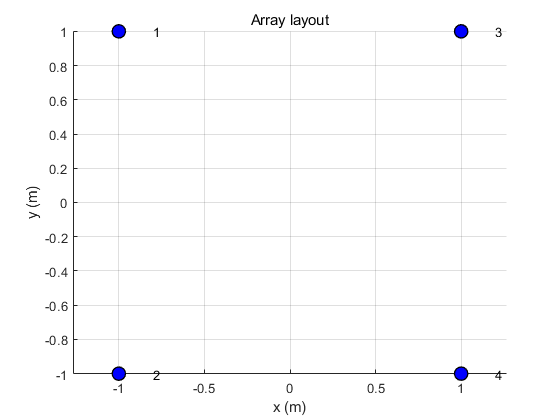

figure
layout(ra)
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **天线阵立体结构的可视化**

**        使用 show 函数展示矩形天线阵的立体结构**

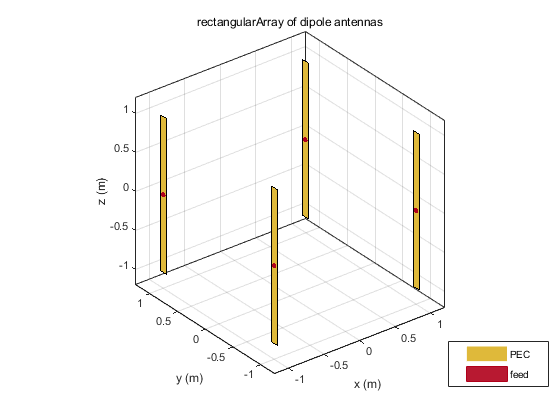

figure
show(ra)
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **绘制天线阵的辐射方向图**

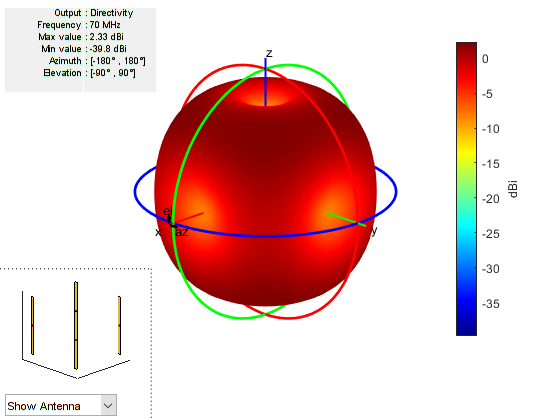

figure
pattern(ra,70e6)

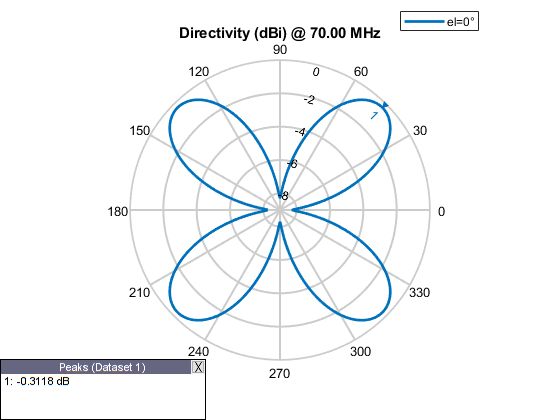

figure
patternAzimuth(ra,70e6)

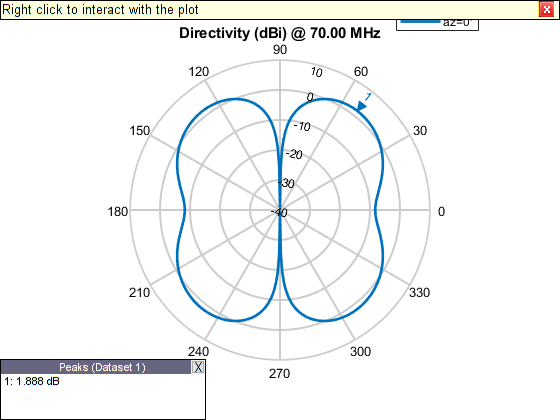

figure
patternElevation(ra,70e6)

- **计算天线阵的方向性系数**

[Directivity]= pattern(ra,70e6,0,90)

Directivity = -39.2495

- **计算天线阵的电场和磁场**

[E,H] = EHfields(ra,70e6,[0;0;1])

E =    0.0000 + 0.0000i
   0.0009 + 0.0015i
  -1.3393 - 0.0711i


H = 1.0e-05 *

  -0.1016 - 0.1843i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


- **绘制天线阵的极化方式**

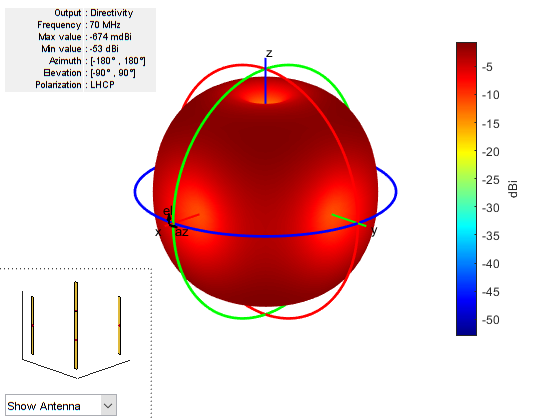

figure
pattern(ra, 70e6,'Polarization','LHCP')

- **计算天线阵的波瓣宽度**

[bw,angles] = beamwidth(ra, 70e6,0,1:1:360)

bw =    44.0000
   44.0000


angles =     28    72
   108   152


- **计算天线阵的有源阻抗**

**        使用impedance 函数计算并绘制天线阵的有源阻抗。有源阻抗或扫描阻抗指的是阵列天线中所有单元天线都被激活时的每个单元天线的输入阻抗。可以通过指定单元天线的序号来分别观察每个单元天线的输入阻抗，也可以通过改变单元天线的序号同时观察全部单元天线的输入阻抗。**

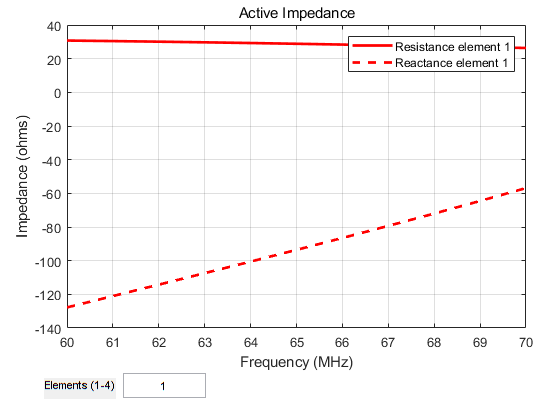

figure
impedance(ra,60e6:1e6:70e6)

set(gcf,'Visible','on');   	    %强制图片弹出显示

- **计算天线阵的反射系数**

**        使用 sparameters 函数计算矩形天线阵的反射系数，并将其保存在一个结构中。对于 **$$$N$$$** 元天线阵来讲，包括如下反射系数，**$$$S_{11},S_{12},\cdots,S_{NN}$$$**，总共有 **$$$N^{2}$$$** 个。下面的语句就用来计算 4 元天线阵在某一个频段的反射系数，并利用 rfplot 函数将其绘制出来。函数中的数字 72 表示的是参考阻抗，用于计算相应的反射系数。**

S = sparameters(ra, 60e6 :1e6 :70e6,72)

S =   sparameters: S-parameters object

       NumPorts: 4
    Frequencies: [11×1 double]
     Parameters: [4×4×11 double]
      Impedance: 72

  rfparam(obj,i,j) returns S-parameter Sij


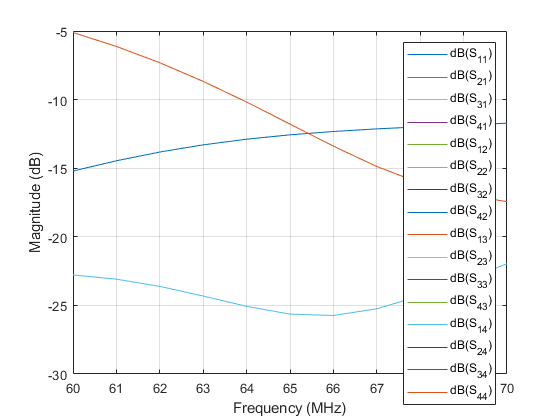

figure
rfplot(S)
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **计算天线阵的回波损耗**

**        使用 returnLoss 函数计算并绘制阵列天线的回波损耗。同样地，可以通过改变单元天线的序号来分别观察每个单元天线的回波损耗，或者同时观察所有单元天线的回波损耗。**

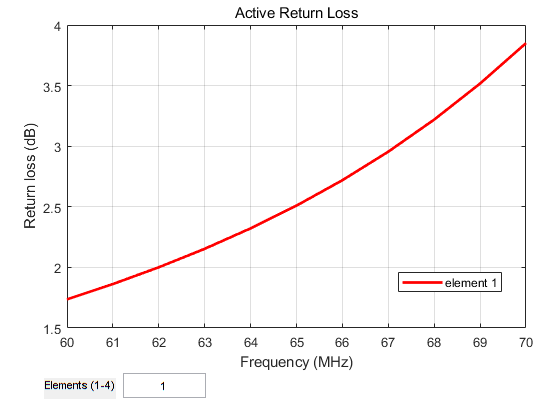

figure
returnLoss(ra,60e6:1e6:70e6,72);

set(gcf,'Visible','on');   	    %强制图片弹出显示